----Reading layers----


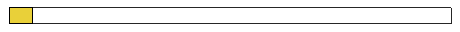

Elapsed time is 3.253009 seconds.


load Test2_SA_05_NoAlpha

addpath VirtualSpeciesFunctions/
addpath Tool/
layerfolder = "Capas/Capas_SouthAmerica_5M/"; %route to folder with ambiental data
Dimensions = ReadLayers(layerfolder);

MEJOR CASO

mejor = [4, 38];

alpha = 2;
Occ = OccupExp(mejor(1));
Sam = SampExp(mejor(1));

Point = Points(mejor(2), :);
coeff = Coeffs(mejor(2), :);

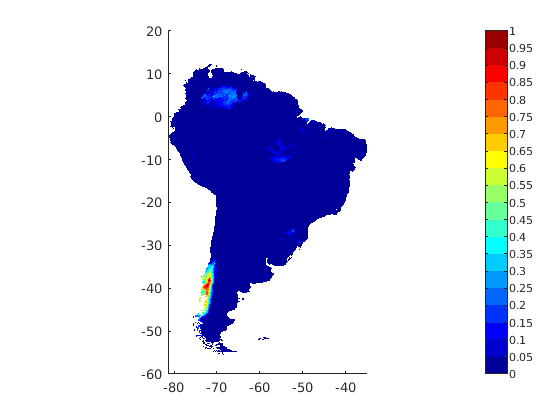

close all
InfoInitialPoint = InitialPoint(Dimensions, Point', coeff');
MapInfo = VirtualSpecies(Dimensions, InfoInitialPoint, Occ, true);

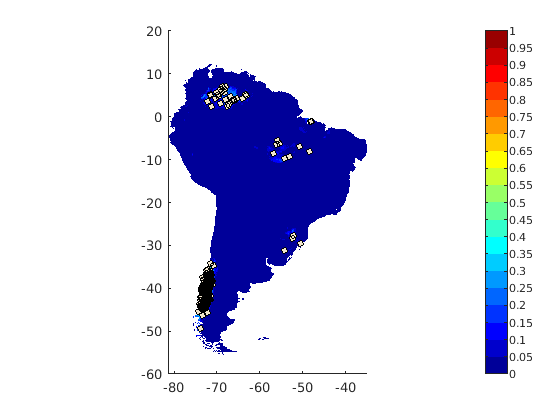

NicheMap = MapInfo.Map;
%   T = samplingVS(Dimensions, MapInfo, Sam, alpha, true, 'GenSP', true);

T = "virtualBest";
data = bnm_prep(T, Dimensions, false, 0.7);

----Finding correlation----
Elapsed time is 0.136879 seconds.
----Creating predictors----
Elapsed time is 0.201638 seconds.
¡All done!


----Modeling----


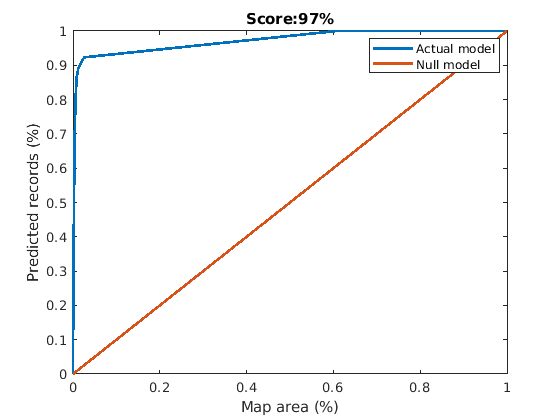

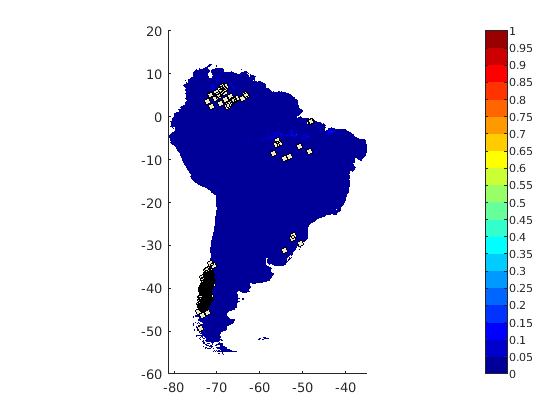

Elapsed time is 0.638595 seconds.


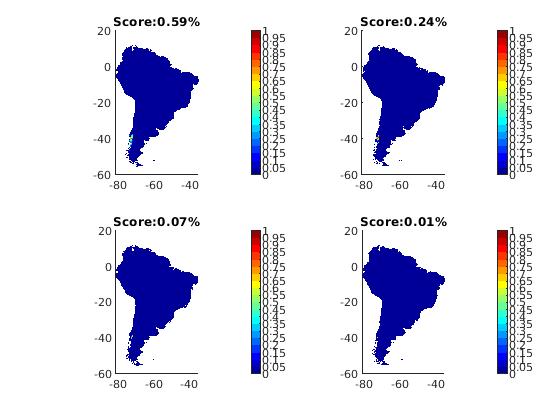

data = bnm_modeling(data, '', true);   

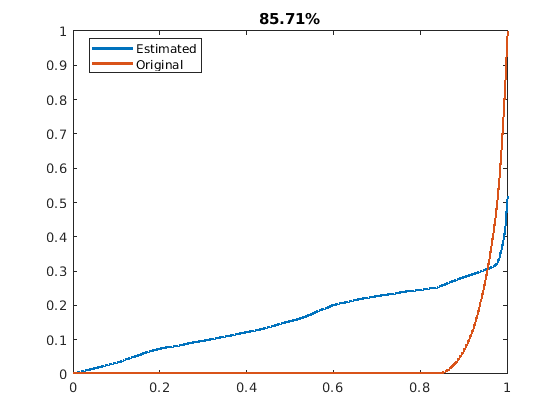

ModelMap = data.Map;
VectorMet = MapMetric(NicheMap, ModelMap, true);

disp(VectorMet)

   0.857127744394719   0.973801036027422



 writetable(T,'virtualBest.csv')

PEOR CASO

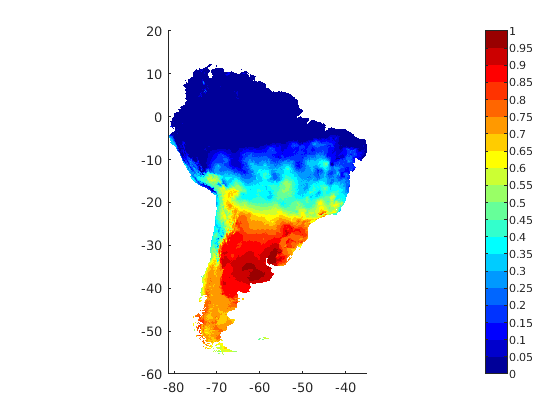

peor = [13, 176];

alpha = 2;
Occ = OccupExp(peor(1));
Sam = SampExp(peor(1));

Point = Points(peor(2), :);
coeff = Coeffs(peor(2), :);

close all
InfoInitialPoint = InitialPoint(Dimensions, Point', coeff');
MapInfo = VirtualSpecies(Dimensions, InfoInitialPoint, Occ, true);

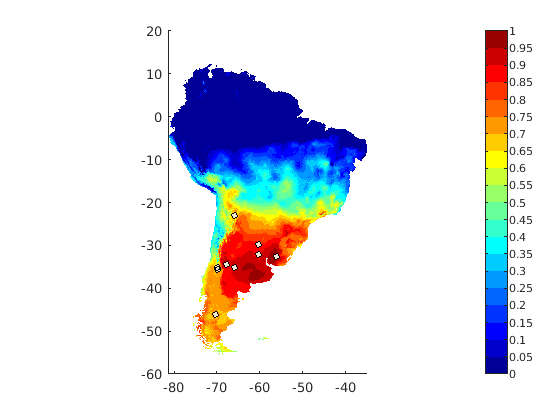

NicheMap = MapInfo.Map;
T = samplingVS(Dimensions, MapInfo, Sam, alpha, true, 'GenSP', true);

% T = "virtualworst";
data = bnm_prep(T, Dimensions, false, 0.7);

----Finding correlation----
Elapsed time is 0.124946 seconds.
----Creating predictors----
Elapsed time is 0.170299 seconds.
¡All done!


----Modeling----


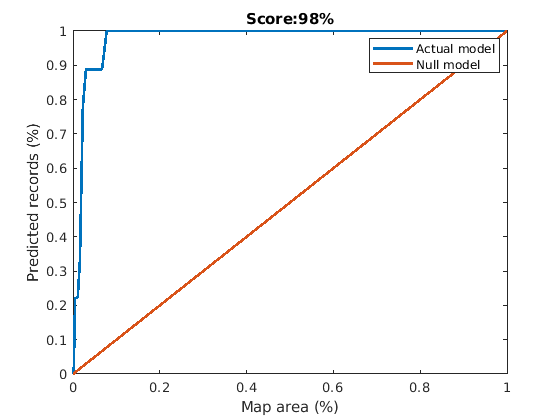

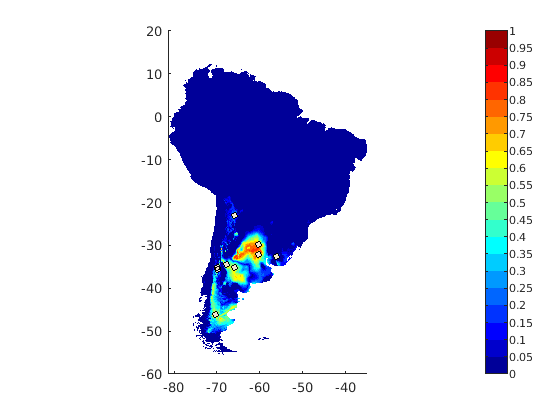

Elapsed time is 0.627622 seconds.


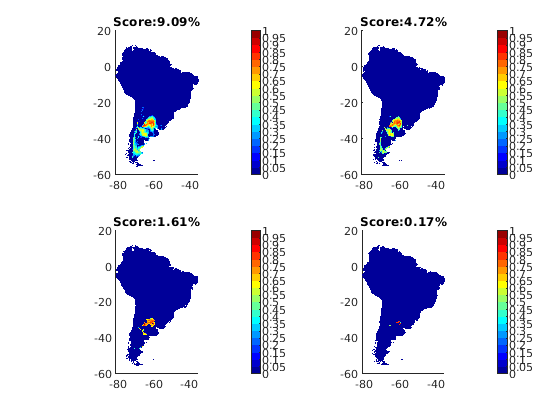

data = bnm_modeling(data, '', true);   

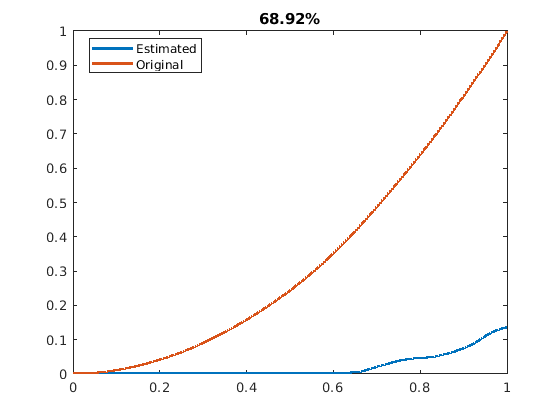

ModelMap = data.Map;
VectorMet = MapMetric(NicheMap, ModelMap, true);

disp(VectorMet)

   0.689152829265203   0.578778266207141



% writetable(T,'virtualworst.csv')